% generateTestFromImage('Test.png');

load('..\LetterTrainingDataset\Training28.mat');
X_train = Value;
y_train = Index;
map = Map;
load('..\LetterTrainingDataset\Testing28.mat');
X_test = Value;
y_test = Index;
bestCorr = 0;
bestEst = zeros(size(y_test));
bestK = 0;

for k = 3:10
    y_est = knn(X_train, y_train, X_test, k);
    correct = y_test == y_est;
    correct = sum(correct(:))/size(y_test, 1);
    disp(['Tested k = ', int2str(k), ', with accuracy ', sprintf('%.3f',correct)]);
    if correct > bestCorr
        bestCorr = correct;
        bestEst = y_est;
        bestK = k;
    end
end

Tested k = 3, with accuracy 0.714
Tested k = 4, with accuracy 0.695
Tested k = 5, with accuracy 0.700
Tested k = 6, with accuracy 0.687
Tested k = 7, with accuracy 0.696
Tested k = 8, with accuracy 0.687
Tested k = 9, with accuracy 0.684
Tested k = 10, with accuracy 0.672


disp(['Best k is ', int2str(bestK), ', with accuracy ', sprintf('%.3f',bestCorr)]);

Best k is 3, with accuracy 0.714


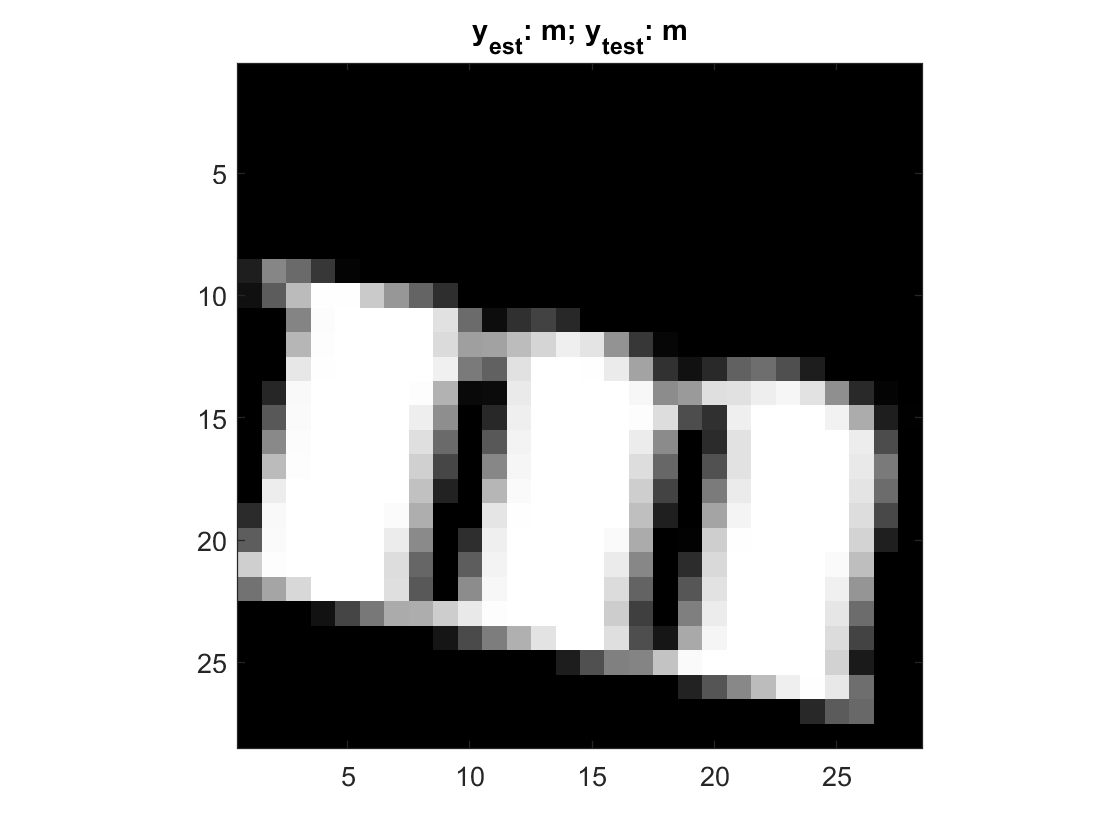

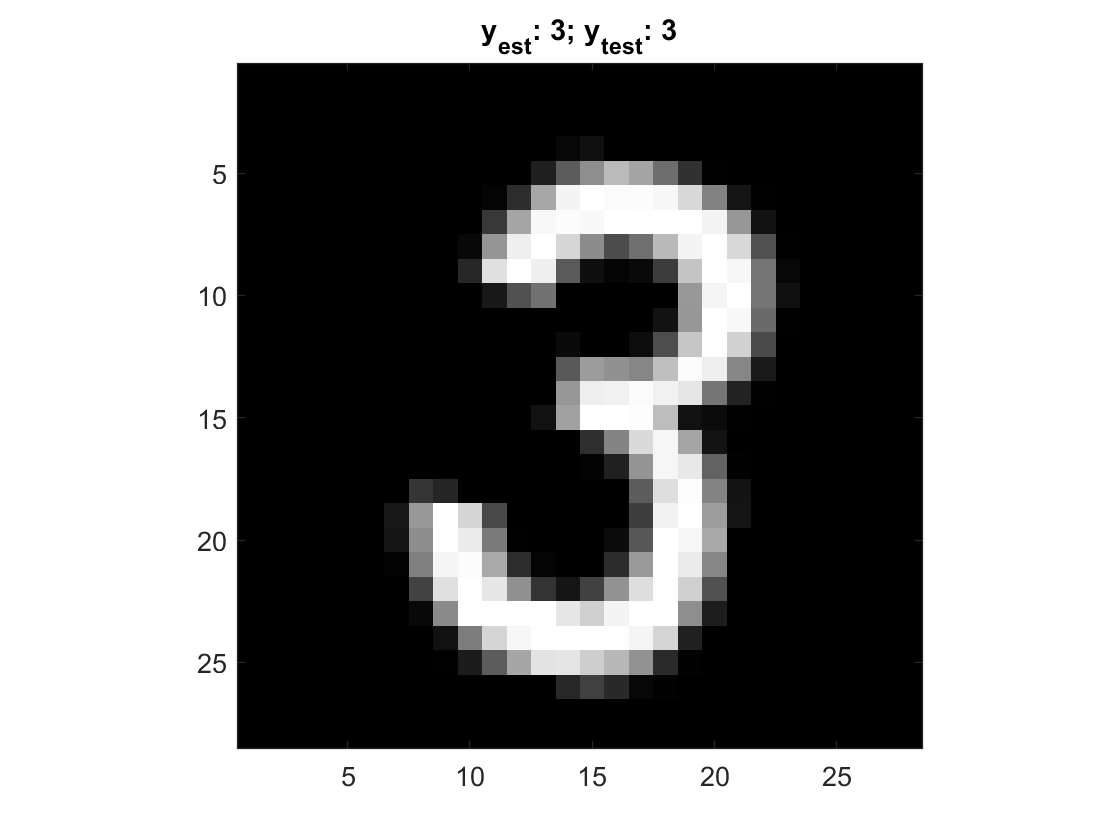

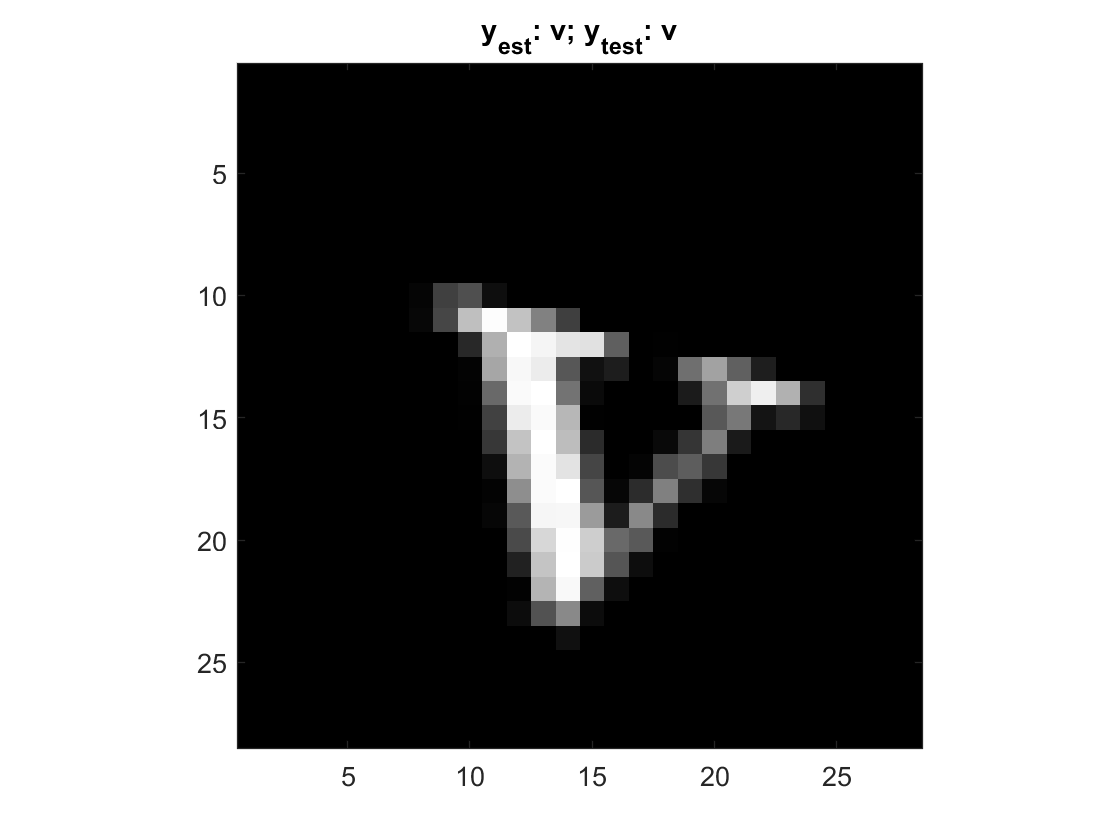

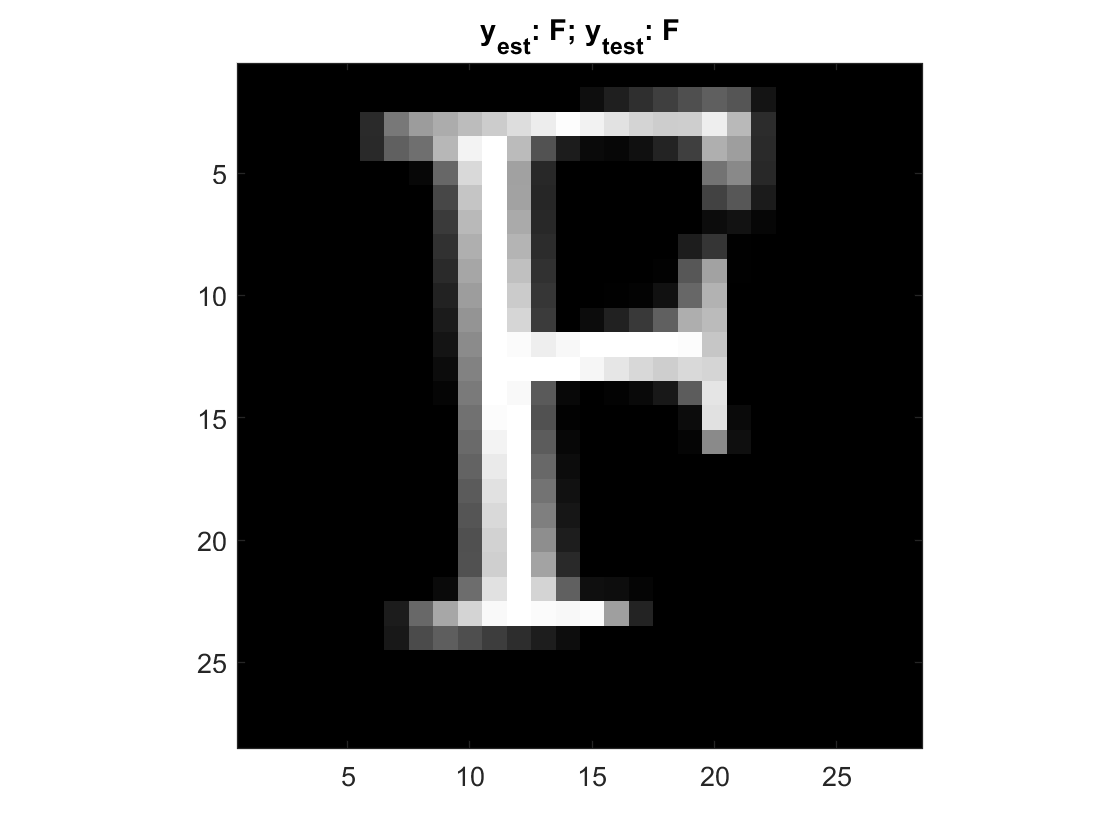

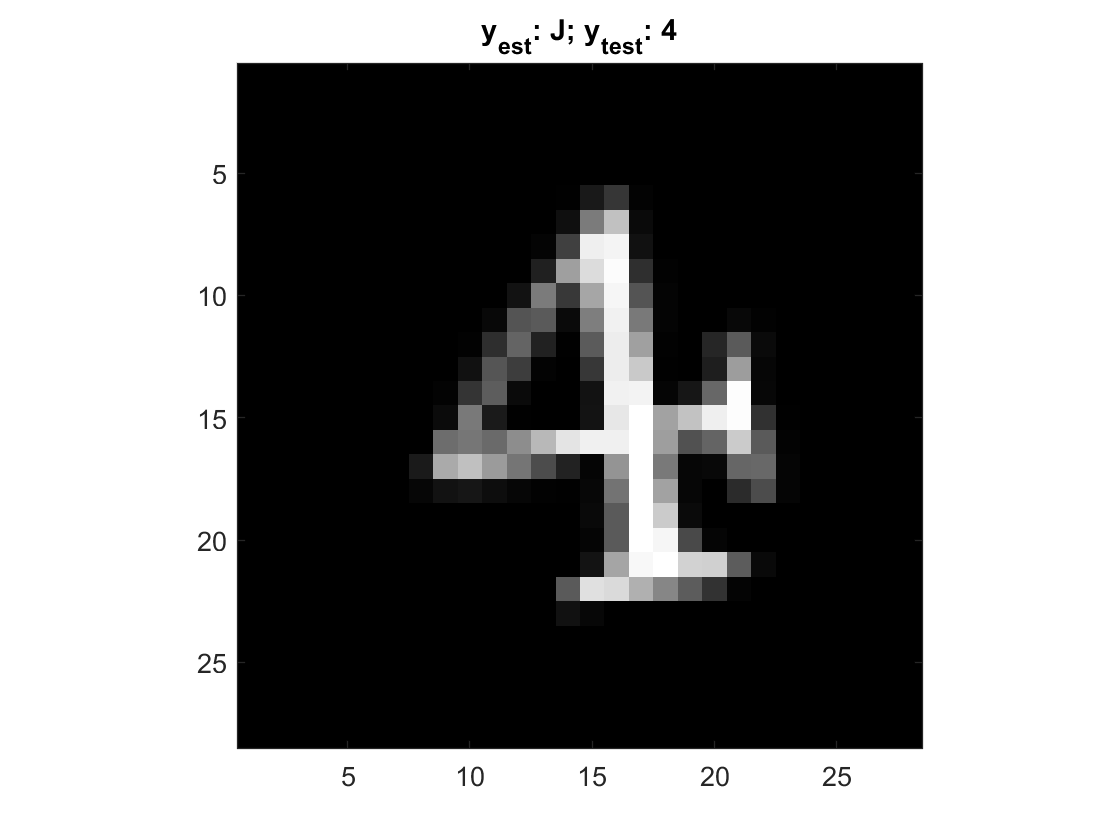

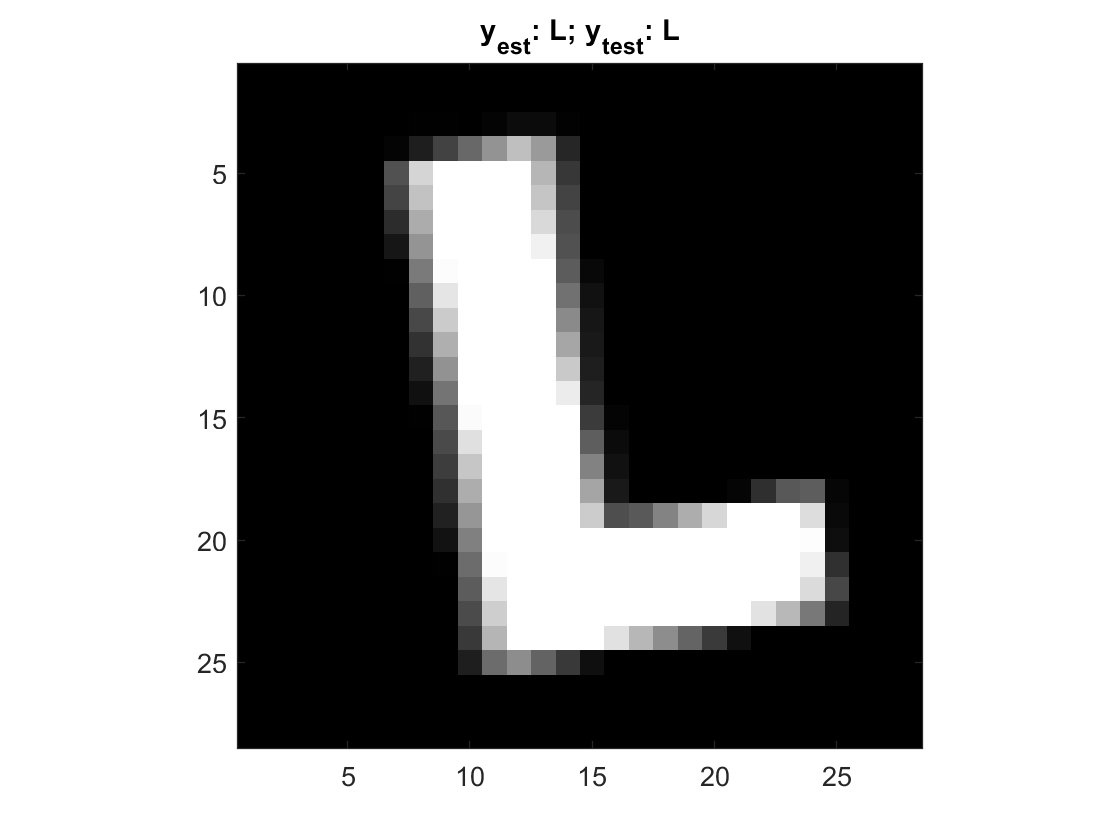

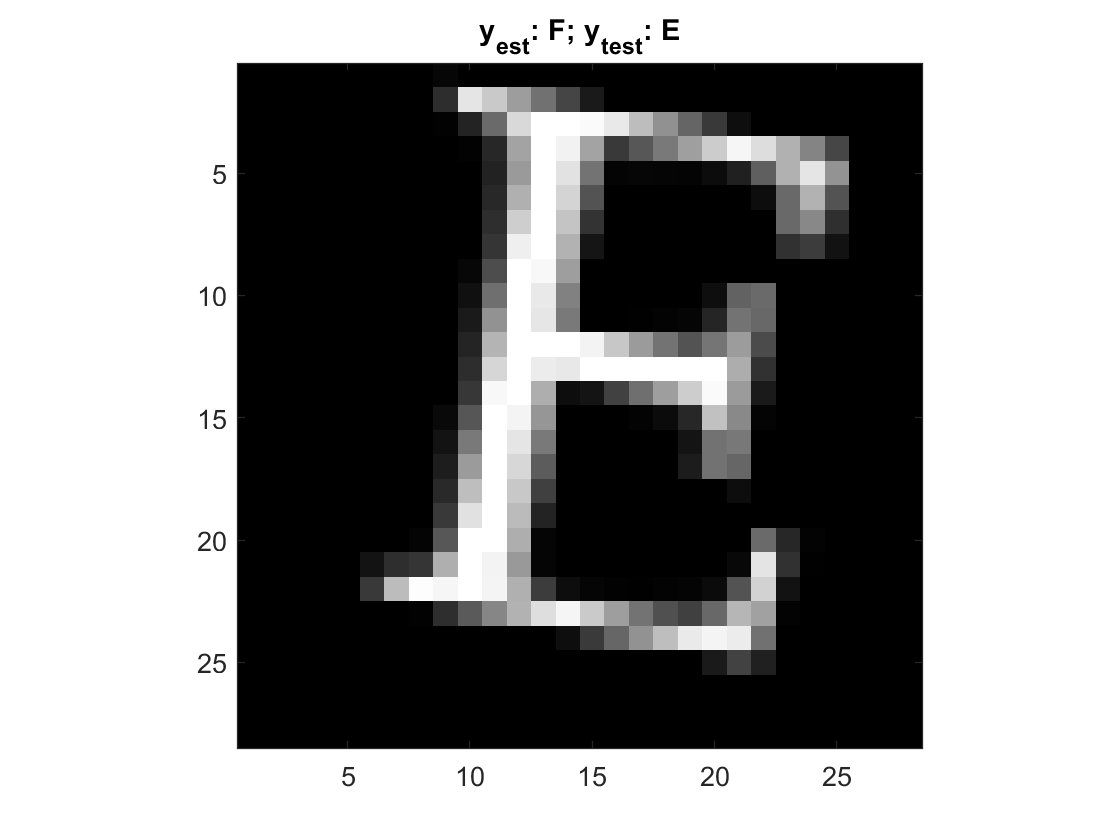

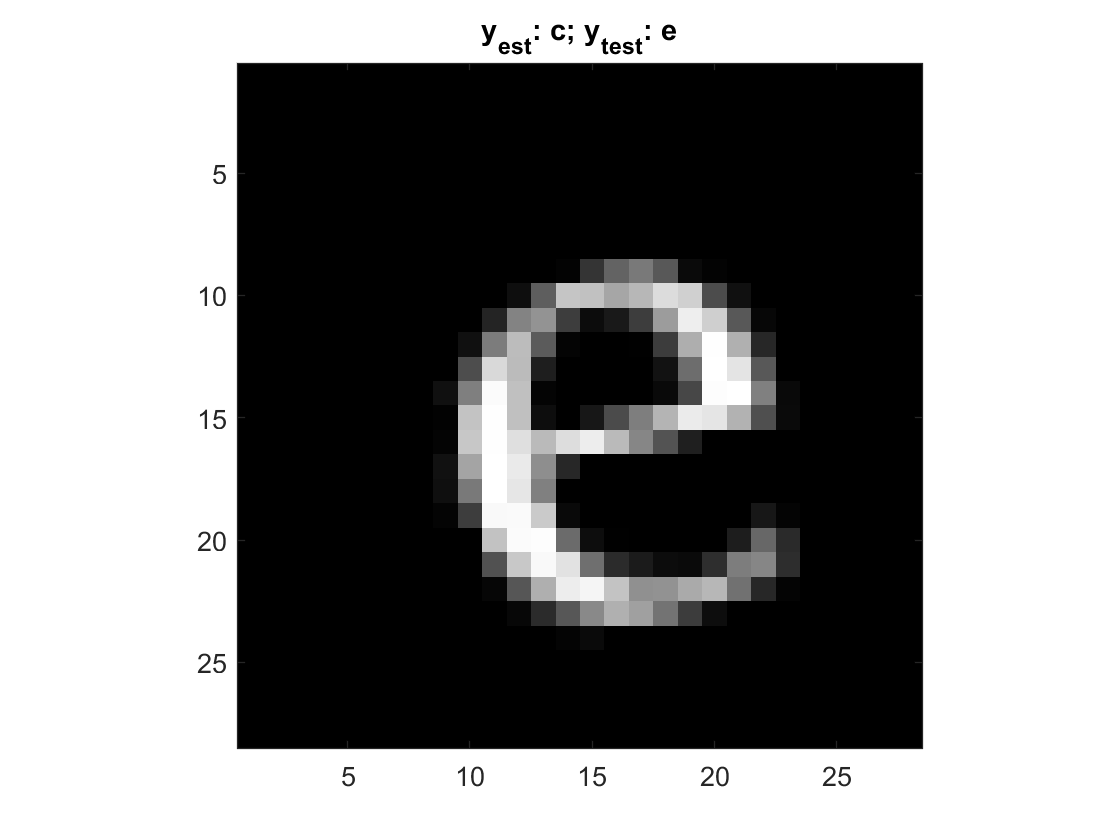

for n = 1:20
    I = reshape(X_test(n,:),[28,28]);
    figure; image(I); pbaspect([1 1 1]); colormap(gray(256));
    title(['y_{est}: ', char(bestEst(n)), '; y_{test}: ', char(y_test(n))]);
end

save('knnResult.mat','y_est');

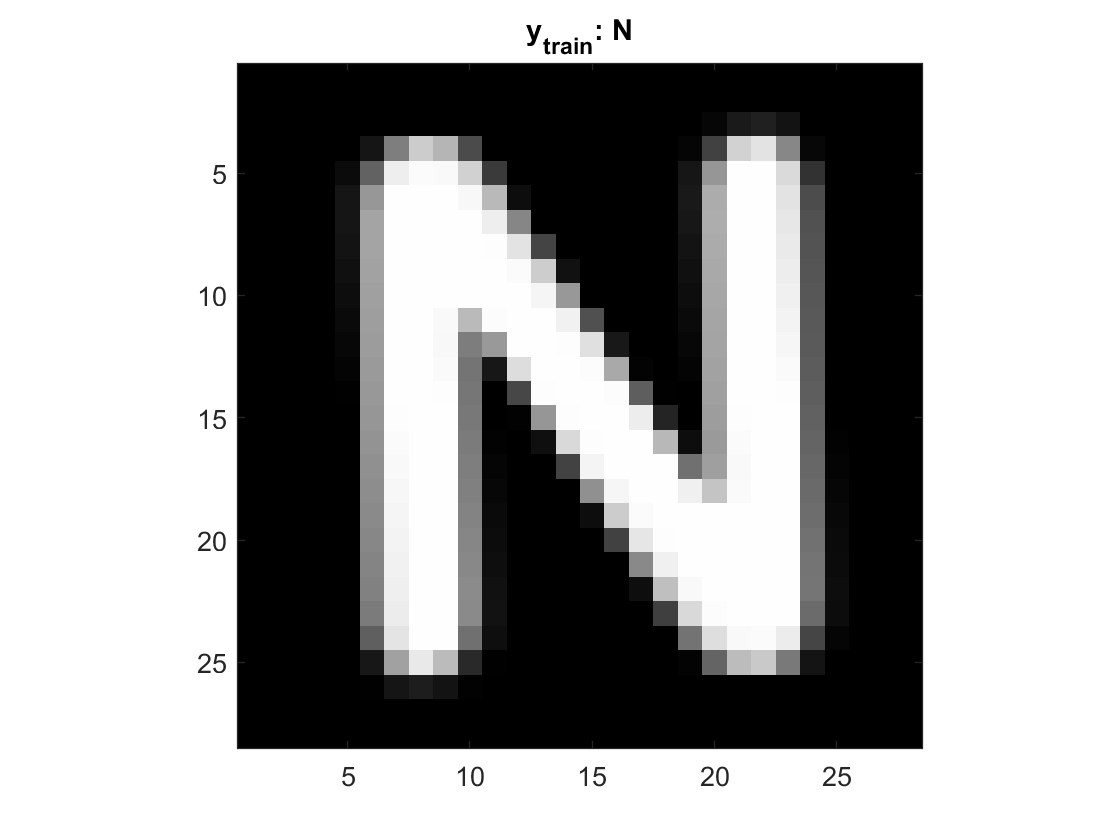

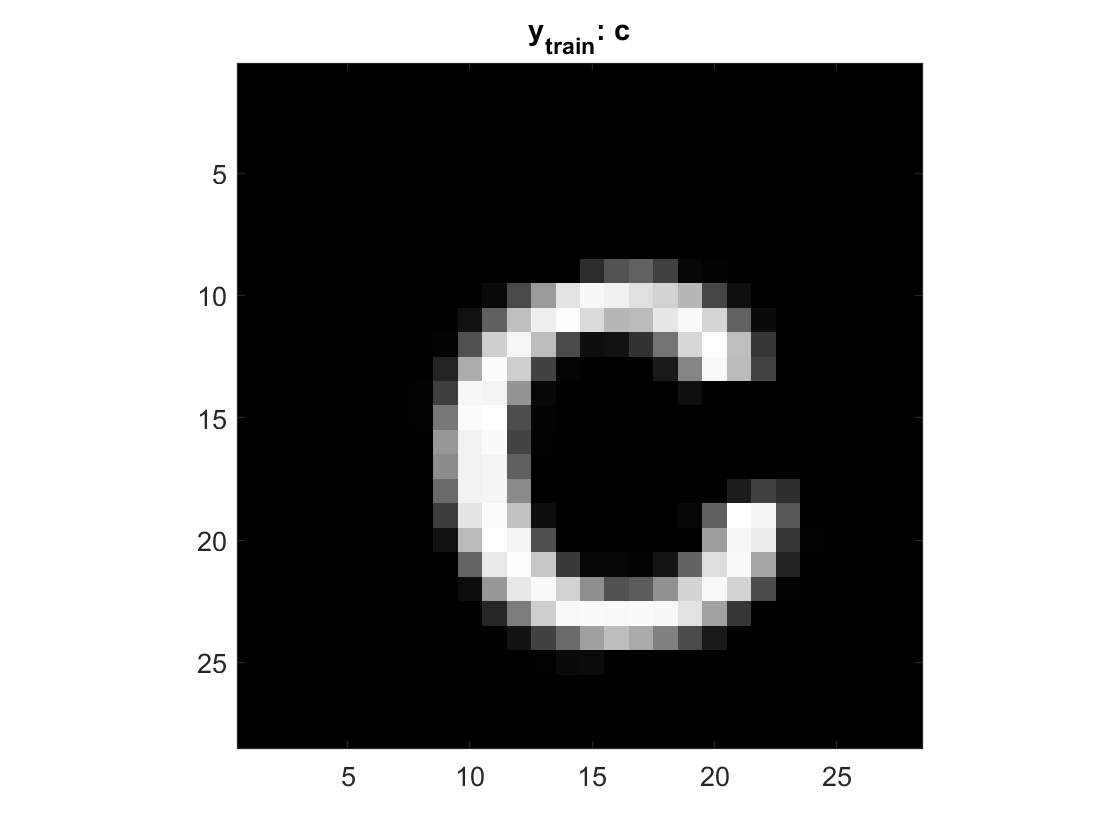

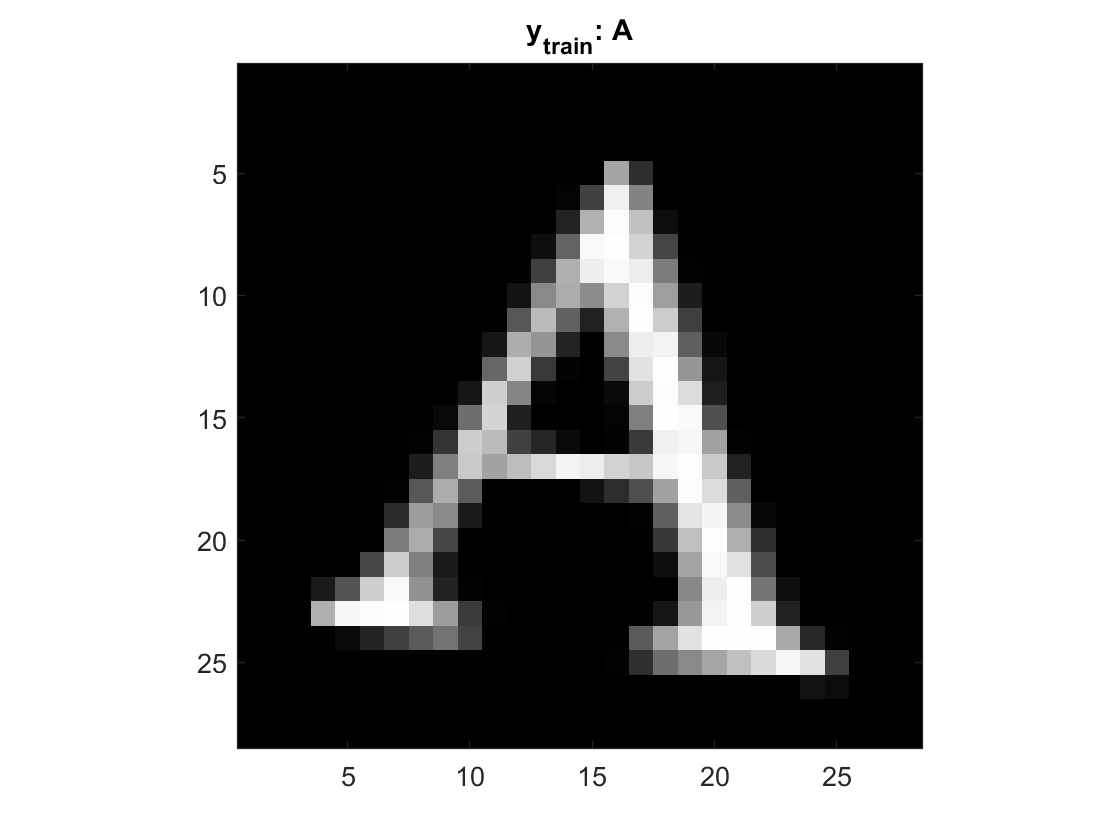

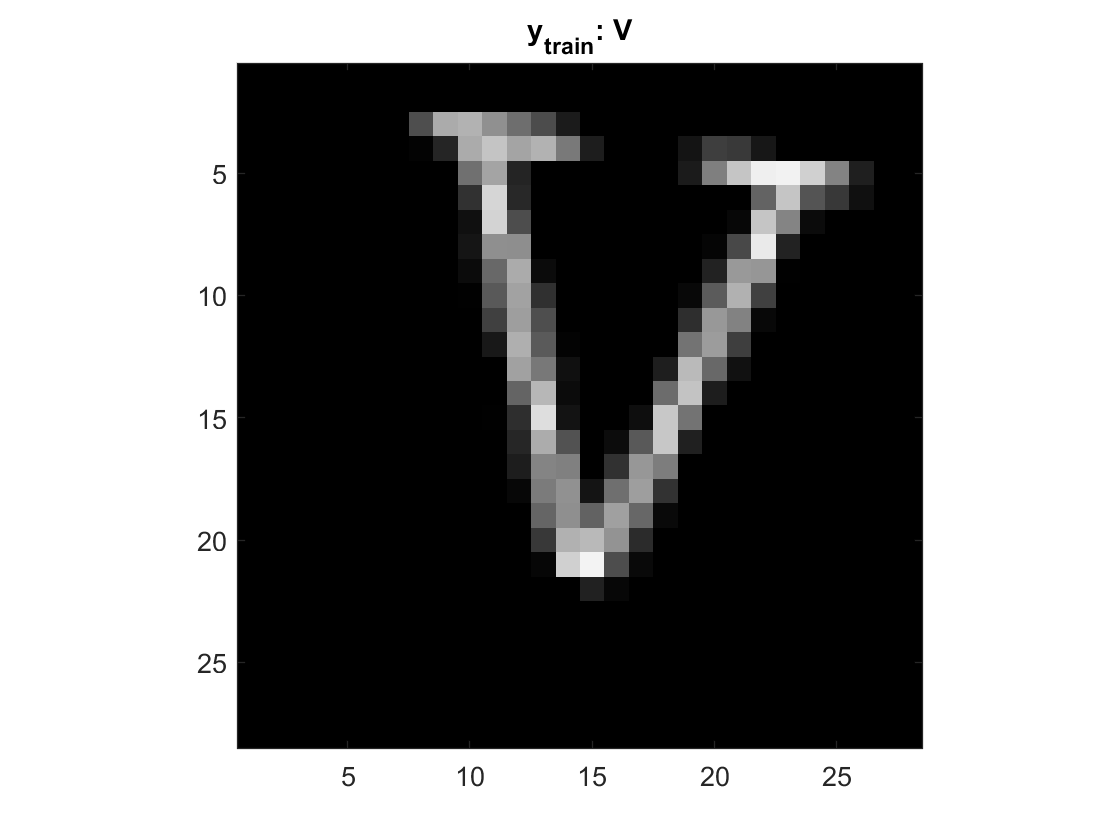

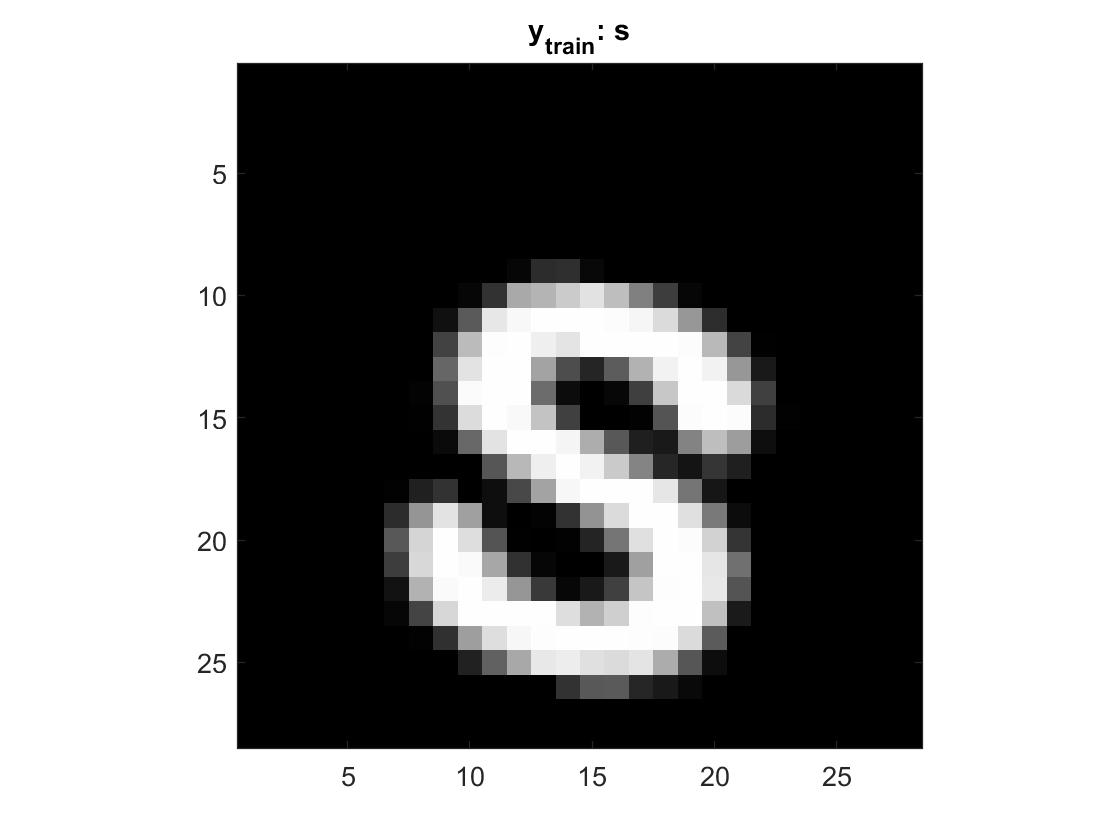

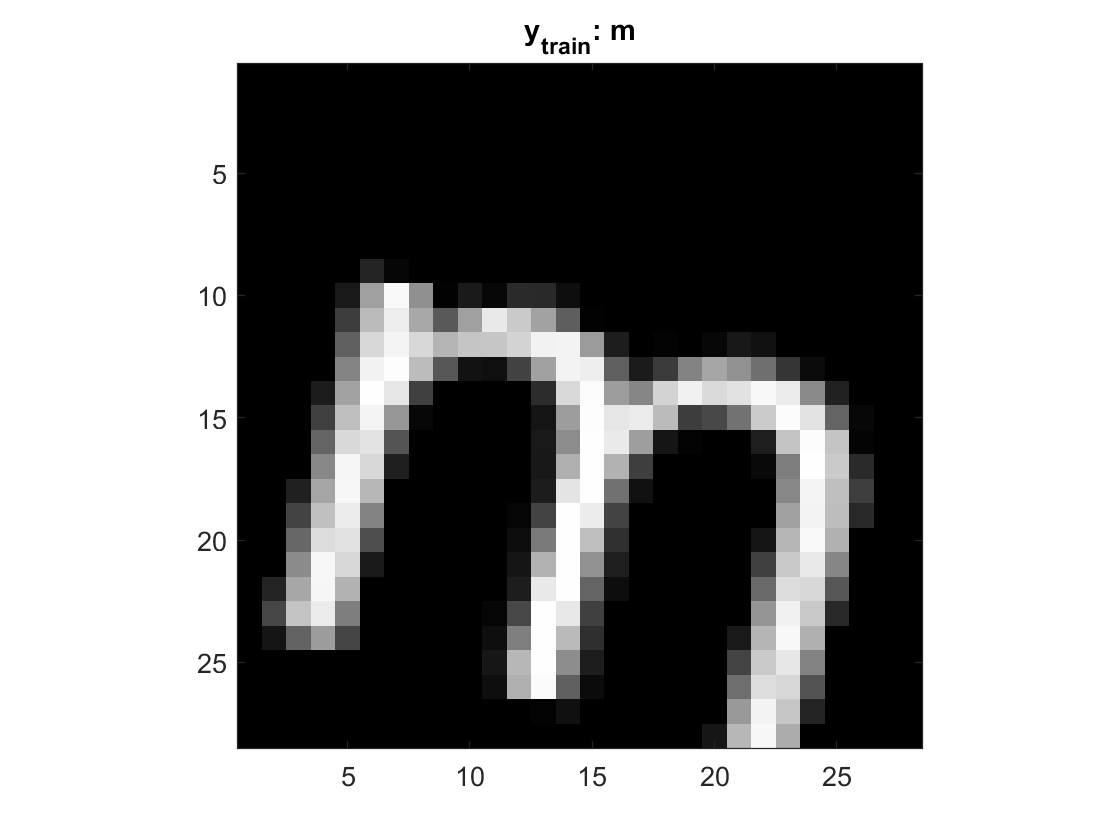

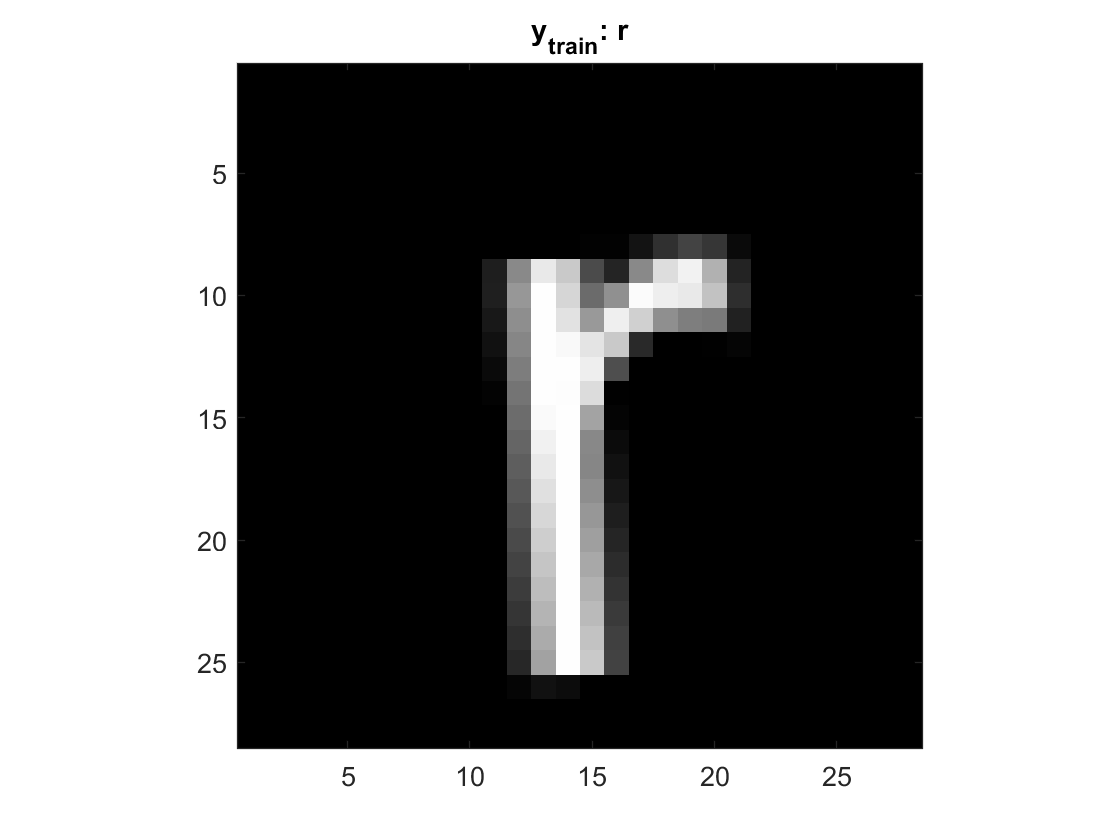

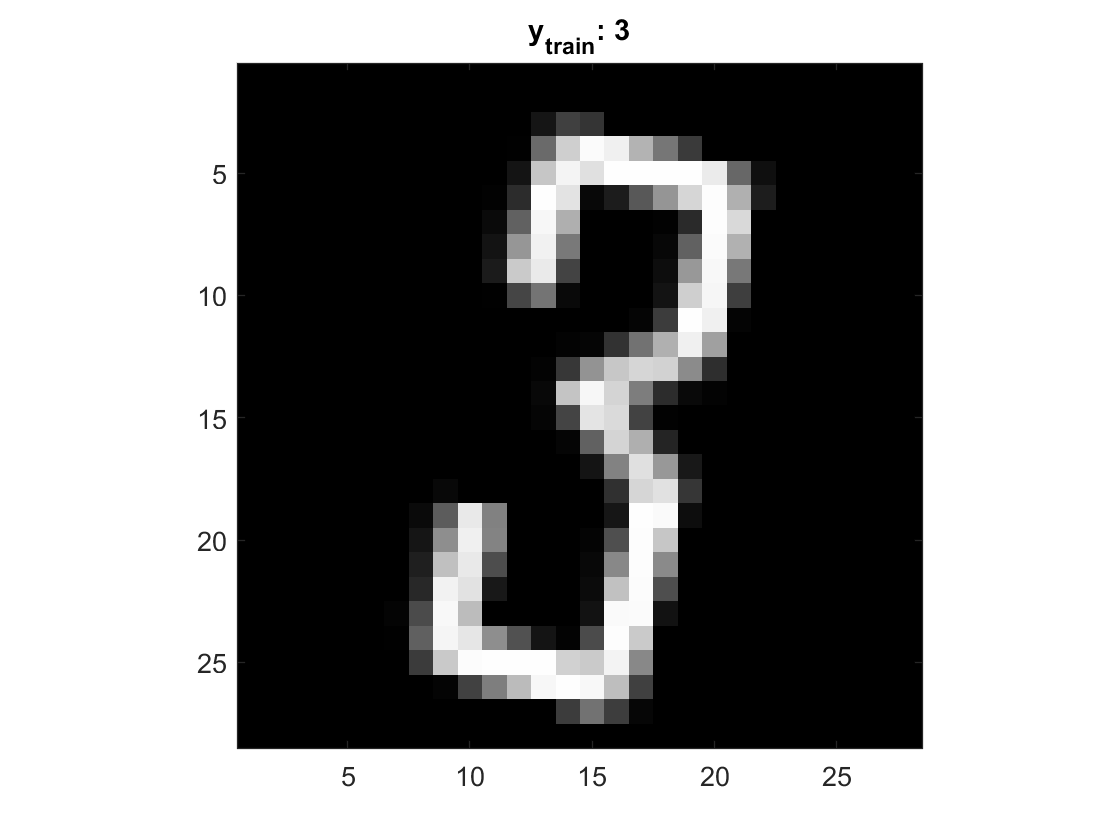

% for n = 1:20
%     I = reshape(X_train(n,:)*255,[28,28]);
%     figure; image(I); pbaspect([1 1 1]); colormap(gray(256));
%     title(['y_{train}: ', char(y_train(n))]);
% end